**Calculer la probabilité d'avoir une vague de chaleur pendant l'été 2022.**

Principe:

On applique la méthode de Monte Carlo sur un grand nombre d'essais. On obtient donc la probabilité souhaitée par le rapport du nombre d'essais concluants sur le nombre d'essais total.

clear all
%Paramètres de la tendance
kappa=0.194; %vitesse de retour à la moyenne
A=6.38; %temperature moyenne annuelle
B=0.0001; 
phi=-154.76;
C=10.44;
omega=365;

%paramètre de la volatilité
gamma=sqrt(6.12);

N_MC=1000;

Tinitiale=-1;
tmin=537;%21 juin
tmax=629;%21 septembre
Tlim=25.3;
T1=zeros(1,tmax);
T1(1)=Tinitiale;
S=0;
for j = 1 : N_MC
    Vague_chaleur=0;

    for i=2:tmax
        T1(i)= T1(i-1) + kappa *(theta(i-1)-T1(i-1)) + dtheta(i-1) + gamma*normrnd(0,1);
    end

    T_ete_2022=T1([tmin:tmax]);

    for i=1:(length(T_ete_2022)-3)
        if T_ete_2022(i)>=Tlim && T_ete_2022(i+1)>=Tlim && T_ete_2022(i+2)>=Tlim;
            Vague_chaleur=1;
        end
    end
    S=S+Vague_chaleur;
end
Probabilite=S/N_MC

Probabilite = 0.1140

Jusqu'à présent nous avons conservé le paramètre de la volatilité constant. Il ne le sera plus dès à présent. 

Voici la fonction gamma qui dépent maintenant du jour et de la période:

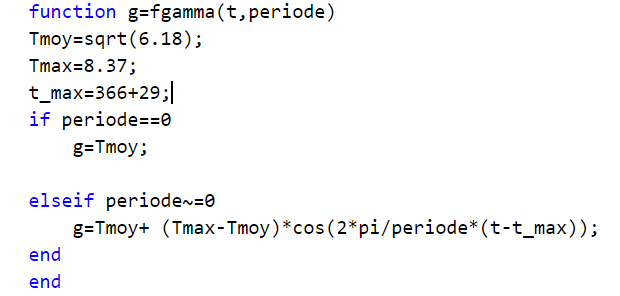

clear Probabilite Proba_gamma_cste periode
N_MC=100;
kappa=0.194;
gamma_max=sqrt(8.37);
Tinitiale=-1;
tmin=537;
tmax=629;
Tlim=25.3;
periode_max=10000;
periode=linspace(0,periode_max,100);
Probabilite=zeros(1,length(periode));
Proba_gamma_cste=zeros(1,length(periode));

for k=1:length(periode)
        T1=zeros(1,tmax);
        T1_gammma_cste=zeros(1,tmax);
        T1(1)=Tinitiale;
        T1_gammma_cste(1)=Tinitiale;
        S=0;
        S_gamma_cste=0;
    for j = 1 : N_MC
        Vague_chaleur=0;
        Vague_chaleur_gamma_cste=0;
        for i=2:tmax
            T1(i)= T1(i-1) + kappa *(theta(i-1)-T1(i-1)) + dtheta(i-1) + fgamma(i,periode(k))*normrnd(0,1);
            T1_gammma_cste(i)= T1_gammma_cste(i-1) + kappa *(theta(i-1)-T1_gammma_cste(i-1)) + dtheta(i-1) + gamma_max*normrnd(0,1);
        end

        T_ete_2022=T1([tmin:tmax]);
        T_ete_2022_gamma_cste=T1_gammma_cste([tmin:tmax]);

        for i=1:(length(T_ete_2022)-3)
            if T_ete_2022(i)>=Tlim && T_ete_2022(i+1)>=Tlim && T_ete_2022(i+2)>=Tlim;
                Vague_chaleur=1;
            end
        end
        S=S+Vague_chaleur;
        for i=1:(length(T_ete_2022)-3)
            if T_ete_2022_gamma_cste(i)>=Tlim && T_ete_2022_gamma_cste(i+1)>=Tlim && T_ete_2022_gamma_cste(i+2)>=Tlim;
                Vague_chaleur_gamma_cste=1;
            end
        end
        S_gamma_cste=S_gamma_cste+Vague_chaleur_gamma_cste;
    end
    Probabilite(k)=S/N_MC;
    Proba_gamma_cste(k)=S_gamma_cste/N_MC;
end

plot(periode,Probabilite)
xlabel('Periode (jour)','FontSize',12)
ylabel('Probalitité d avoir une vague de chaleur','FontSize',12)
Probabilite;
hold on
Tendance=Probabilite([80:100]);
Moyenne_tendance=mean(Tendance)

Moyenne_tendance = 0.2390

plot([0,periode_max],[Moyenne_tendance,Moyenne_tendance])
hold on 
Moyenne_gamma_cste=mean(Proba_gamma_cste)

Moyenne_gamma_cste = 0.2371

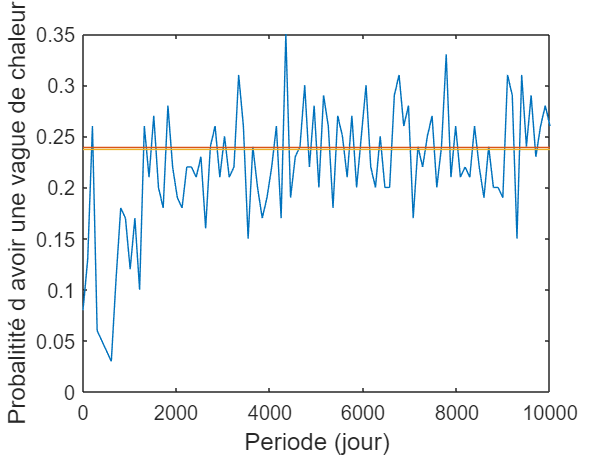

plot([0,periode_max],[Moyenne_gamma_cste,Moyenne_gamma_cste])
hold off